%==========================================================================
% Author:    Naghmeh Akhavan, PhD
% Affil.:    University of Michigan, Ann Arbor
% Contact:   nakhavan@umich.edu
%
%
% Last updated: March 2026
%==========================================================================

close all; clear; clc;

%% ---------------- Settings ----------------
combinedFolder  = 'C:\Users\naghm\OneDrive\Desktop\combined_out';
matR            = fullfile(combinedFolder,'Combined_BigResultTable.mat');
matD            = fullfile(combinedFolder,'Combined_BigStageDetailsTable.mat');

WAKE_BREAK_MIN  = 2;
WAKE_BREAK_SEC  = WAKE_BREAK_MIN * 60;   % 120 s

SAVE_FIG     = false;   % set true if we want PNGs
SAVE_TAB     = true;    % save subject-count filter table

outPng_proxy = fullfile(combinedFolder,'tables_out', ...
                 sprintf('Fig_REM_deciles_proxy_longwake%g_IQRsubj.png', WAKE_BREAK_MIN));
outPng_time  = fullfile(combinedFolder,'tables_out', ...
                 sprintf('Fig_REM_deciles_time_longwake%g_IQRsubj.png', WAKE_BREAK_MIN));
outPng_dur   = fullfile(combinedFolder,'tables_out', ...
                 sprintf('Fig_REM_deciles_meanBoutDur_ONSET_POOLED_longwake%g_IQRsubj.png', WAKE_BREAK_MIN));

% 10 segments (deciles) on [0,1]
decileEdges01 = linspace(0,1,11);
decileMidsPct = 100 * (decileEdges01(1:end-1) + decileEdges01(2:end))/2;
nDec = 10;

% Subject cycle-count IQR filter
APPLY_SUBJECT_CYCLECOUNT_IQR_FILTER = true;
IQR_K = 1.5;

%% ---------------- Load ----------------
assert(isfile(matR), 'Missing %s', matR);
assert(isfile(matD), 'Missing %s', matD);

SR = load(matR);  R = SR.Combined_BigResultTable;
SD = load(matD);  D = SD.Combined_BigStageDetailsTable;

fprintf('Loaded:\n  %s\n  %s\n', matR, matD);

Loaded:
  C:\Users\naghm\OneDrive\Desktop\combined_out\Combined_BigResultTable.mat
  C:\Users\naghm\OneDrive\Desktop\combined_out\Combined_BigStageDetailsTable.mat



%% ---------------- Normalize types ----------------
R.Subject_Index = string(R.Subject_Index);

if ~ismember("REM_Cycle_Index", string(R.Properties.VariableNames))
    R.REM_Cycle_Index = strings(height(R),1);
end
R.REM_Cycle_Index = string(R.REM_Cycle_Index);

needR = ["IREM","NREM","Wake","Movement"];
for v = needR
    if ~ismember(v, string(R.Properties.VariableNames))
        R.(v) = NaN(height(R),1);
    end
    R.(v) = double(R.(v));
end


if (~ismember("IREM", string(R.Properties.VariableNames))) || all(isnan(R.IREM))
    if all(ismember(["NREM","Wake","Movement"], string(R.Properties.VariableNames)))
        R.IREM = double(R.NREM) + double(R.Wake) + double(R.Movement);
        fprintf('IREM reconstructed as NREM + Wake + Movement.\n');
    else
        error('Cannot reconstruct IREM: missing NREM/Wake/Movement.');
    end
else
    R.IREM = double(R.IREM);
end

% Stage details table D
if ~ismember("Stage", string(D.Properties.VariableNames))
    error('Stage column not found in stage table.');
end
if ~ismember("Duration", string(D.Properties.VariableNames))
    error('Duration column not found in stage table.');
end
if ~ismember("REM_Cycle_Index", string(D.Properties.VariableNames))
    error('Stage table missing REM_Cycle_Index.');
end

D.Stage           = double(D.Stage);
D.Duration        = double(D.Duration);
D.REM_Cycle_Index = string(D.REM_Cycle_Index);

%% ---------------- Long-wake DROP ----------------
WAKE_CODE = 5;   

if ~ismember("ord", string(D.Properties.VariableNames))
    D.ord = (1:height(D))';
end
D = sortrows(D, {'REM_Cycle_Index','ord'});

[Gd, keys]  = findgroups(D.REM_Cycle_Index);
hasLongWake = false(numel(keys),1);

for gi = 1:numel(keys)
    rows = find(Gd == gi);
    st   = D.Stage(rows);
    du   = D.Duration(rows);
    if any(isfinite(st) & isfinite(du) & (st == WAKE_CODE) & (du >= WAKE_BREAK_SEC))
        hasLongWake(gi) = true;
    end
end

FlagTab = table(keys, hasLongWake, ...
    'VariableNames', {'REM_Cycle_Index','HasLongWake'});

R = outerjoin(R, FlagTab, ...
    'Keys','REM_Cycle_Index', ...
    'MergeKeys',true, ...
    'Type','left');

if ~ismember("HasLongWake", string(R.Properties.VariableNames))
    R.HasLongWake = false(height(R),1);
else
    R.HasLongWake = logical(fillmissing(double(R.HasLongWake), 'constant', 0));
end

maskDrop = (R.HasLongWake == 1);
nDrop    = sum(maskDrop);
Rkeep    = R(~maskDrop, :);

fprintf('Long-wake DROP: Wake >= %d min (>= %d s) — dropped %d cycles; kept %d.\n', ...
        WAKE_BREAK_MIN, WAKE_BREAK_SEC, nDrop, height(Rkeep));

Long-wake DROP: Wake >= 2 min (>= 120 s) — dropped 1028 cycles; kept 3994.



%% ---------------- Common setup ----------------
Rkeep.Subject_Index = string(Rkeep.Subject_Index);
Rkeep.IREM = double(Rkeep.IREM);

% Panel (2) requires REMpost for time-fraction split
if ~ismember("REMpost", string(Rkeep.Properties.VariableNames))
    error('Combined_BigResultTable missing REMpost column (needed for REM time plot).');
end
Rkeep.REMpost = double(Rkeep.REMpost);

% Panel (3) should match Single/Sequential: prefer REMpre if available
useREMpre = ismember("REMpre", string(Rkeep.Properties.VariableNames));
if useREMpre
    Rkeep.REMpre = double(Rkeep.REMpre);
    REMDUR_NAME = "REMpre";
else
    REMDUR_NAME = "REMpost";  % fallback
    warning('REMpre not found. Panel (3) will use REMpost instead.');
end

%% ---------------- Subject cycle-count IQR filter ----------------
valid_for_count = isfinite(Rkeep.IREM) & (Rkeep.IREM >= 0) & ...
                  isfinite(Rkeep.REMpost) & (Rkeep.REMpost > 0) & ...
                  strlength(strtrim(Rkeep.Subject_Index)) > 0;

if useREMpre
    % still count cycles if REMpost is valid; REMpre is not required for counting
end

removedSubjects = strings(0,1);
cycleCountTab   = table();

Rcount = Rkeep(valid_for_count, :);
assert(~isempty(Rcount), 'No valid cycles remain for subject cycle-count filtering.');

if APPLY_SUBJECT_CYCLECOUNT_IQR_FILTER
    [Gs, subjNames] = findgroups(Rcount.Subject_Index);
    cycleCounts = splitapply(@numel, Rcount.Subject_Index, Gs);

    cycleCountTab = table(subjNames, cycleCounts, ...
        'VariableNames', {'Subject_Index','KeptCycleCount'});

    q1 = local_quantile(cycleCounts, 0.25);
    q3 = local_quantile(cycleCounts, 0.75);
    iqrVal = q3 - q1;

    lo = q1 - IQR_K * iqrVal;
    hi = q3 + IQR_K * iqrVal;

    isOutlierSubject = (cycleCounts < lo) | (cycleCounts > hi);
    removedSubjects  = subjNames(isOutlierSubject);

    fprintf(['Subject cycle-count IQR filter:\n' ...
             '  Q1 = %.3f, Q3 = %.3f, IQR = %.3f\n' ...
             '  Lower bound = %.3f, Upper bound = %.3f\n' ...
             '  Removed subjects = %d of %d\n'], ...
             q1, q3, iqrVal, lo, hi, sum(isOutlierSubject), numel(subjNames));

    if ~isempty(removedSubjects)
        Rkeep = Rkeep(~ismember(Rkeep.Subject_Index, removedSubjects), :);
        fprintf('  Cycles remaining after subject removal: %d\n', height(Rkeep));
    else
        fprintf('  No subject removed by the IQR filter.\n');
    end
else
    fprintf('Subject cycle-count IQR filter: OFF\n');
end

Subject cycle-count IQR filter:
  Q1 = 3.000, Q3 = 9.000, IQR = 6.000
  Lower bound = -6.000, Upper bound = 18.000
  Removed subjects = 20 of 541


  Cycles remaining after subject removal: 3483


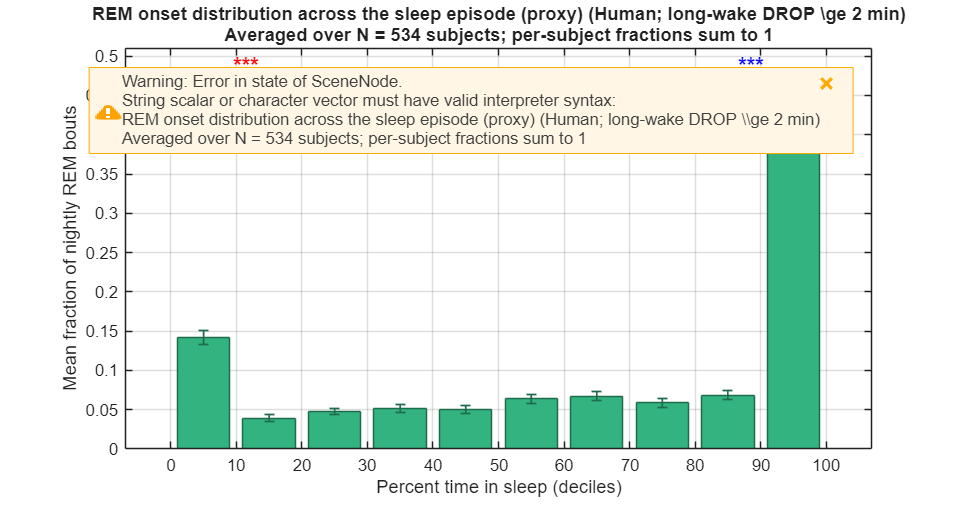


assert(~isempty(Rkeep), 'No cycles remain after subject cycle-count filtering.');

%% =======================================================================
% (1) REM onset distribution (fraction of nightly bouts)  [SUBJECT-AVERAGED]
% =======================================================================
valid_proxy = isfinite(Rkeep.IREM) & (Rkeep.IREM >= 0) & ...
              strlength(strtrim(Rkeep.Subject_Index)) > 0;

rec = string(Rkeep.Subject_Index);
[G, recNames] = findgroups(rec);
REMfrac_bouts = NaN(numel(recNames), nDec);    % per-subject fractions (bouts)

for gi = 1:numel(recNames)
    idxAll = find(G == gi);
    idx    = idxAll(valid_proxy(idxAll));
    if isempty(idx), continue; end

    IREM_sec = Rkeep.IREM(idx);
    IREM_sec(~isfinite(IREM_sec)) = 0;

    % proxy clock: cycle duration = IREM only
    cycDur = IREM_sec;
    sCum   = [0; cumsum(cycDur)];
    totalNight = sCum(end);
    if totalNight <= 0, continue; end

    decAbs = decileEdges01 * totalNight;

    % REM onsets at end of IREM
    REM_onsets = sCum(1:end-1) + IREM_sec;
    ok = isfinite(REM_onsets);
    REM_onsets = REM_onsets(ok);
    if isempty(REM_onsets), continue; end

    % Make the last edge inclusive
    binID = discretize(REM_onsets, decAbs);
    if ~isempty(REM_onsets)
        atRightEdge = (REM_onsets == decAbs(end));
        binID(atRightEdge) = nDec;
    end

    counts = accumarray(binID(~isnan(binID)), 1, [nDec,1], @sum, 0);

    totBouts = sum(counts);
    if totBouts > 0
        REMfrac_bouts(gi,:) = (counts(:) / totBouts).';
    end
end

keepRows = any(isfinite(REMfrac_bouts), 2);
REMfrac_bouts = REMfrac_bouts(keepRows, :);

if isempty(REMfrac_bouts)
    error('No subjects with computable REM onset fractions after filtering.');
end

mREM_proxy  = mean(REMfrac_bouts, 1, 'omitnan');
sREM_proxy  = std(REMfrac_bouts, 0, 1, 'omitnan');
nSubj_proxy = size(REMfrac_bouts, 1);
seREM_proxy = sREM_proxy / max(1, sqrt(nSubj_proxy));

figure('Color','w','Position',[100 100 840 440]);
face = [0.20 0.70 0.50];
edge = face * 0.6;

bar(decileMidsPct, mREM_proxy, 'FaceColor', face, 'EdgeColor', edge);
hold on;
errorbar(decileMidsPct, mREM_proxy, seREM_proxy, ...
         'LineStyle','none', 'Color', edge, 'LineWidth', 1);

xlabel('Percent time in sleep (deciles)');
ylabel('Mean fraction of nightly REM bouts');
title({sprintf('REM onset distribution across the sleep episode (proxy) (Human; long-wake DROP \\ge %d min)', WAKE_BREAK_MIN), ...
       sprintf('Averaged over N = %d subjects; per-subject fractions sum to 1', nSubj_proxy)});

ylim([0, max(0.001, 1.1*max(mREM_proxy + seREM_proxy))]);
grid on; box on;


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Hypothesis tests: edge deciles vs middle deciles (subject-level, paired)
x_first = REMfrac_bouts(:,1);
x_last  = REMfrac_bouts(:,10);
x_mid   = mean(REMfrac_bouts(:,2:9), 2, 'omitnan');

[p_first, ~] = paired_signflip_pvalue(x_first, x_mid, 20000);
[p_last,  ~] = paired_signflip_pvalue(x_last,  x_mid, 20000);

% Make room for significance brackets
yl = ylim;
ylim([0, yl(2)*1.10]);
yl = ylim;
yTop = yl(2);

% x-locations
xL  = decileMidsPct(1);    % first bar center
xR  = decileMidsPct(10);   % last bar center
xM1 = decileMidsPct(2);    % middle group left edge
xM2 = decileMidsPct(9);    % middle group right edge

% geometry
arm = 0.012 * yTop;

% ----- middle-group bracket -----
yMid = 0.86 * yTop;
plot([xM1 xM1 xM2 xM2], [yMid-arm yMid yMid yMid-arm], ...
    'k-', 'LineWidth', 1.5);

% ----- left comparison: first bar vs middle group -----
% Use a separate bracket whose right side ends above the left half of middle group
xLM = xM1 + 3;
yLeft = 0.92 * yTop;
plot([xL xL xLM xLM], [yLeft-arm yLeft yLeft yLeft-arm], ...
    'k-', 'LineWidth', 1.5);

% ----- right comparison: last bar vs middle group -----
% Use a separate bracket whose left side starts above the right half of middle group
xRM = xM2 - 3;
yRight = 0.92 * yTop;
plot([xRM xRM xR xR], [yRight-arm yRight yRight yRight-arm], ...
    'k-', 'LineWidth', 1.5);

% Significance labels
if p_first == 0
    labL = '***';
else
    labL = '*';
end

if p_last == 0
    labR = '***';
else
    labR = '*';
end

text(mean([xL xLM]), yLeft + 0.004*yTop, labL, ...
    'HorizontalAlignment','center', ...
    'VerticalAlignment','bottom', ...
    'FontSize', 13, 'FontWeight','bold', 'Color','r');

text(mean([xRM xR]), yRight + 0.004*yTop, labR, ...
    'HorizontalAlignment','center', ...
    'VerticalAlignment','bottom', ...
    'FontSize', 13, 'FontWeight','bold', 'Color','b');

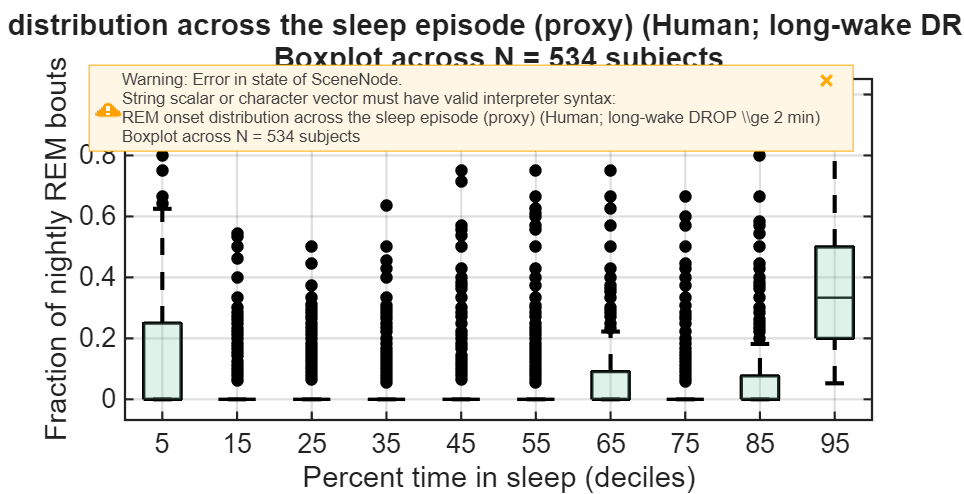


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

if SAVE_FIG
    outDir = fileparts(outPng_proxy);
    if ~isfolder(outDir), mkdir(outDir); end
    exportgraphics(gcf, outPng_proxy, 'Resolution', 300);
    fprintf('Saved: %s\n', outPng_proxy);
end

%% ---------------- Boxplot: Panel (1) REM onset distribution ----------------
figure('Color','w','Position',[110 110 860 440]);

boxData1 = REMfrac_bouts;   % subject x decile

lbl1 = strings(nDec,1);
for bi = 1:nDec
    lbl1(bi) = sprintf('%.0f', decileMidsPct(bi));
end

boxplot(boxData1, ...
    'Labels', cellstr(lbl1), ...
    'Symbol', 'k.', ...
    'Whisker', 1.5, ...
    'Colors', [0 0 0]);

hOut = findobj(gca,'Tag','Outliers');
set(hOut, 'Marker','o', 'MarkerSize',7, ...
    'MarkerEdgeColor','k', 'MarkerFaceColor','k');

grid on; box on;
xlabel('Percent time in sleep (deciles)');
ylabel('Fraction of nightly REM bouts');

title({sprintf('REM onset distribution across the sleep episode (proxy) (Human; long-wake DROP \\ge %d min)', WAKE_BREAK_MIN), ...
       sprintf('Boxplot across N = %d subjects', nSubj_proxy)});

set(gca,'FontSize',16);
set(gca,'LineWidth',1.3);

set(findobj(gca,'Tag','Box')    , 'LineWidth',2.0, 'Color',[0 0 0]);
set(findobj(gca,'Tag','Median') , 'LineWidth',2.4, 'Color',[0 0 0]);
set(findobj(gca,'Tag','Whisker'), 'LineWidth',2.5, 'Color',[0 0 0]);
set(findobj(gca,'Tag','Cap')    , 'LineWidth',2.5, 'Color',[0 0 0]);

ax = gca;
hW = findobj(ax,'Tag','Whisker');
if isempty(hW)
    hW = [findobj(ax,'Tag','Upper Whisker'); findobj(ax,'Tag','Lower Whisker')];
end
set(hW,'LineWidth',2.5);

hC = findobj(ax,'Tag','Cap');
if isempty(hC)
    hC = [findobj(ax,'Tag','Upper Adjacent Value'); findobj(ax,'Tag','Lower Adjacent Value')];
end
set(hC,'LineWidth',2.5);

hold on;
COL = [0.20 0.70 0.50];
cFill = lighten_color(COL, 0.35);

h = findobj(gca,'Tag','Box');
h = flipud(h);
for j = 1:numel(h)
    xd = get(h(j),'XData');
    yd = get(h(j),'YData');
    patch(xd, yd, cFill, 'FaceAlpha',0.25, 'EdgeColor','none');
end

med = findobj(gca,'Tag','Median');
set(med,'Color',[0 0 0],'LineWidth',1.4);
hold off;

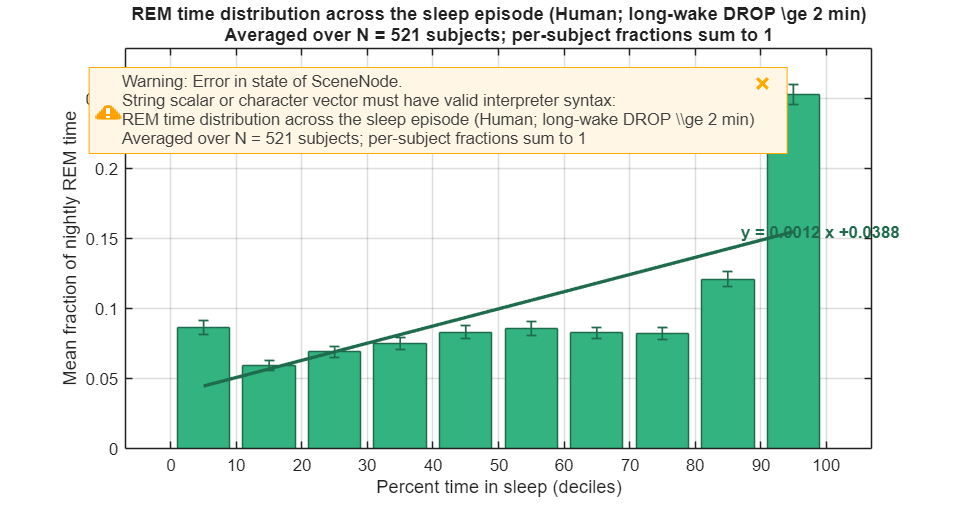


if SAVE_FIG
    outPng_proxy_box = fullfile(combinedFolder,'tables_out', ...
        sprintf('Fig_REM_deciles_proxy_BOXPLOT_longwake%g_IQRsubj.png', WAKE_BREAK_MIN));
    exportgraphics(gcf, outPng_proxy_box, 'Resolution', 300);
    fprintf('Saved: %s\n', outPng_proxy_box);
end

%% =======================================================================
% (2) REM time distribution (fraction of nightly REM time) [SUBJECT-AVERAGED]
%     Uses REMpost and overlap-split across deciles
% =======================================================================
valid_time = isfinite(Rkeep.IREM) & (Rkeep.IREM >= 0) & ...
             isfinite(Rkeep.REMpost) & (Rkeep.REMpost > 0) & ...
             strlength(strtrim(Rkeep.Subject_Index)) > 0;

rec2 = string(Rkeep.Subject_Index);
[G2, recNames2] = findgroups(rec2);
REMfrac_time = NaN(numel(recNames2), nDec);    % per-subject fractions (time)

for gi = 1:numel(recNames2)
    idxAll = find(G2 == gi);
    idx    = idxAll(valid_time(idxAll));
    if isempty(idx), continue; end

    IREM_sec    = Rkeep.IREM(idx);
    REMpost_sec = Rkeep.REMpost(idx);

    IREM_sec(~isfinite(IREM_sec))       = 0;
    REMpost_sec(~isfinite(REMpost_sec)) = 0;

    % Full cycle duration = IREM + REMpost
    cycDur = IREM_sec + REMpost_sec;
    sCum   = [0; cumsum(cycDur)];
    totalNight = sCum(end);
    if totalNight <= 0, continue; end

    decAbs = decileEdges01 * totalNight;

    remPerDecile = zeros(nDec,1);
    for c = 1:numel(REMpost_sec)
        a = sCum(c) + IREM_sec(c);   % REM start
        b = a + REMpost_sec(c);      % REM end
        if ~(isfinite(a) && isfinite(b) && b > a), continue; end

        for d = 1:nDec
            L = overlap_len(a, b, decAbs(d), decAbs(d+1));
            if L > 0
                remPerDecile(d) = remPerDecile(d) + L;
            end
        end
    end

    totREM = sum(REMpost_sec(isfinite(REMpost_sec)));
    if totREM > 0
        REMfrac_time(gi,:) = (remPerDecile(:) / totREM).';
    end
end

keepRowsT = any(isfinite(REMfrac_time), 2);
REMfrac_time = REMfrac_time(keepRowsT, :);

if isempty(REMfrac_time)
    error('No subjects with computable REM time fractions after filtering.');
end

mREM_time  = mean(REMfrac_time, 1, 'omitnan');
sREM_time  = std(REMfrac_time, 0, 1, 'omitnan');
nSubj_time = size(REMfrac_time, 1);
seREM_time = sREM_time / max(1, sqrt(nSubj_time));

figure('Color','w','Position',[120 120 840 440]);
faceT = [0.20 0.70 0.50];
edgeT = faceT * 0.6;

bar(decileMidsPct, mREM_time, 'FaceColor', faceT, 'EdgeColor', edgeT);
hold on;
errorbar(decileMidsPct, mREM_time, seREM_time, ...
         'LineStyle','none', 'Color', edgeT, 'LineWidth', 1);

xlabel('Percent time in sleep (deciles)');
ylabel('Mean fraction of nightly REM time');
title({sprintf('REM time distribution across the sleep episode (Human; long-wake DROP \\ge %d min)', WAKE_BREAK_MIN), ...
       sprintf('Averaged over N = %d subjects; per-subject fractions sum to 1', nSubj_time)});

ylim([0, max(0.001, 1.1*max(mREM_time + seREM_time))]);
grid on; box on;

if sum(isfinite(mREM_time)) >= 2
    p2 = polyfit(decileMidsPct, mREM_time, 1);
    yfit2 = polyval(p2, decileMidsPct);
    plot(decileMidsPct, yfit2, '-', 'LineWidth', 2, 'Color', edgeT);
    eqnStr2 = sprintf('y = %.4f x %+ .4f', p2(1), p2(2));
    text(decileMidsPct(end)-8, yfit2(end), eqnStr2, 'Color', edgeT, ...
         'FontSize',10, 'FontWeight','bold');
end

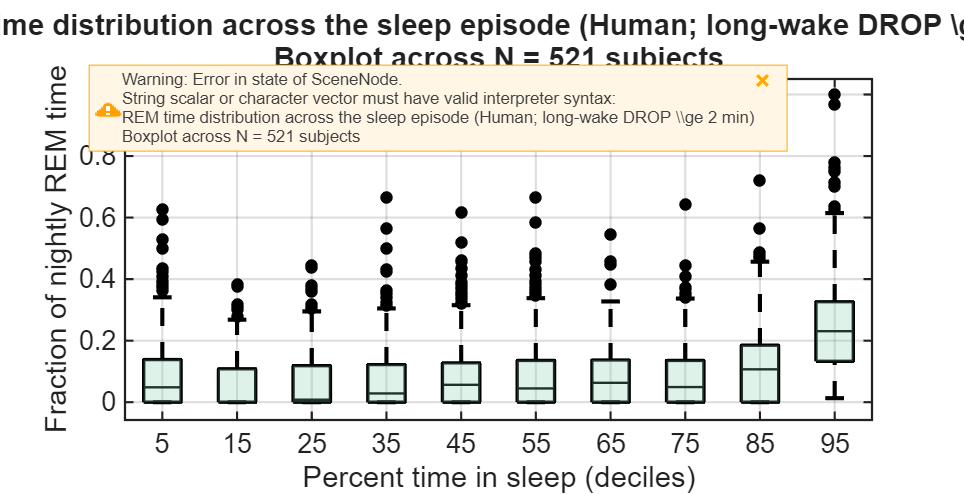


if SAVE_FIG
    outDir = fileparts(outPng_time);
    if ~isfolder(outDir), mkdir(outDir); end
    exportgraphics(gcf, outPng_time, 'Resolution', 300);
    fprintf('Saved: %s\n', outPng_time);
end

%% ---------------- Boxplot: Panel (2) REM time distribution ----------------
figure('Color','w','Position',[130 130 860 440]);

boxData2 = REMfrac_time;   % subject x decile

lbl2 = strings(nDec,1);
for bi = 1:nDec
    lbl2(bi) = sprintf('%.0f', decileMidsPct(bi));
end

boxplot(boxData2, ...
    'Labels', cellstr(lbl2), ...
    'Symbol', 'k.', ...
    'Whisker', 1.5, ...
    'Colors', [0 0 0]);

hOut = findobj(gca,'Tag','Outliers');
set(hOut, 'Marker','o', 'MarkerSize',7, ...
    'MarkerEdgeColor','k', 'MarkerFaceColor','k');

grid on; box on;
xlabel('Percent time in sleep (deciles)');
ylabel('Fraction of nightly REM time');

title({sprintf('REM time distribution across the sleep episode (Human; long-wake DROP \\ge %d min)', WAKE_BREAK_MIN), ...
       sprintf('Boxplot across N = %d subjects', nSubj_time)});

set(gca,'FontSize',16);
set(gca,'LineWidth',1.3);

set(findobj(gca,'Tag','Box')    , 'LineWidth',2.0, 'Color',[0 0 0]);
set(findobj(gca,'Tag','Median') , 'LineWidth',2.4, 'Color',[0 0 0]);
set(findobj(gca,'Tag','Whisker'), 'LineWidth',2.5, 'Color',[0 0 0]);
set(findobj(gca,'Tag','Cap')    , 'LineWidth',2.5, 'Color',[0 0 0]);

ax = gca;
hW = findobj(ax,'Tag','Whisker');
if isempty(hW)
    hW = [findobj(ax,'Tag','Upper Whisker'); findobj(ax,'Tag','Lower Whisker')];
end
set(hW,'LineWidth',2.5);

hC = findobj(ax,'Tag','Cap');
if isempty(hC)
    hC = [findobj(ax,'Tag','Upper Adjacent Value'); findobj(ax,'Tag','Lower Adjacent Value')];
end
set(hC,'LineWidth',2.5);

hold on;
COL = [0.20 0.70 0.50];
cFill = lighten_color(COL, 0.35);

h = findobj(gca,'Tag','Box');
h = flipud(h);
for j = 1:numel(h)
    xd = get(h(j),'XData');
    yd = get(h(j),'YData');
    patch(xd, yd, cFill, 'FaceAlpha',0.25, 'EdgeColor','none');
end

med = findobj(gca,'Tag','Median');
set(med,'Color',[0 0 0],'LineWidth',1.4);
hold off;

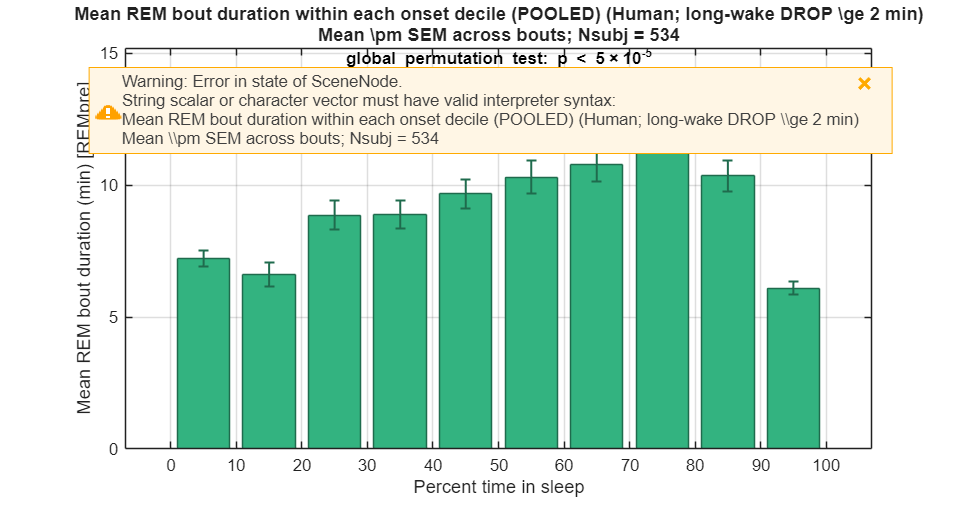


if SAVE_FIG
    outPng_time_box = fullfile(combinedFolder,'tables_out', ...
        sprintf('Fig_REM_deciles_time_BOXPLOT_longwake%g_IQRsubj.png', WAKE_BREAK_MIN));
    exportgraphics(gcf, outPng_time_box, 'Resolution', 300);
    fprintf('Saved: %s\n', outPng_time_box);
end

%% =======================================================================
% (3) MEAN REM BOUT DURATION WITHIN EACH ONSET DECILE  [POOLED]
% =======================================================================
if useREMpre
    REMdur_sec_all = double(Rkeep.REMpre);
else
    REMdur_sec_all = double(Rkeep.REMpost);
end

valid_dur = isfinite(Rkeep.IREM) & (Rkeep.IREM >= 0) & ...
            isfinite(REMdur_sec_all) & (REMdur_sec_all > 0) & ...
            strlength(strtrim(Rkeep.Subject_Index)) > 0;

IREM_min_all   = double(Rkeep.IREM) ./ 60;
REMdur_min_all = REMdur_sec_all ./ 60;

rec3 = string(Rkeep.Subject_Index);
[G3, recNames3] = findgroups(rec3);

REM_onsetFrac = NaN(height(Rkeep),1);

for gi = 1:numel(recNames3)
    idx = find(G3 == gi);
    idx = idx(valid_dur(idx));
    if isempty(idx), continue; end

    I  = IREM_min_all(idx);
    Rm = REMdur_min_all(idx);

    I(~isfinite(I)  | I  < 0) = 0;
    Rm(~isfinite(Rm) | Rm < 0) = 0;

    CycleDur = I + Rm;
    total = sum(CycleDur);
    if total <= 0, continue; end

    cumStart = [0; cumsum(CycleDur(1:end-1))];
    onsetMin = cumStart + I;

    REM_onsetFrac(idx) = onsetMin / total;
end

binEdges = linspace(0,1,11);
binMids  = 100 * (binEdges(1:end-1) + binEdges(2:end)) / 2;

binID = discretize(REM_onsetFrac, binEdges);
atRightEdge = (REM_onsetFrac == binEdges(end));
binID(atRightEdge) = nDec;

ok = isfinite(binID) & ~isnan(binID) & (binID >= 1) & (binID <= nDec) & valid_dur;
b  = double(binID(ok));
y  = REMdur_min_all(ok);

meanDur = NaN(1,nDec);
semDur  = NaN(1,nDec);
sdDur   = NaN(1,nDec);
nDur    = zeros(1,nDec);

for d = 1:nDec
    yd = y(b == d);
    nDur(d) = numel(yd);
    if nDur(d) >= 1
        meanDur(d) = mean(yd, 'omitnan');
        if nDur(d) >= 2
            sdDur(d)  = std(yd, 0, 'omitnan');
            semDur(d) = sdDur(d) / sqrt(nDur(d));
        else
            sdDur(d)  = 0;
            semDur(d) = 0;
        end
    end
end

nSubj_included = numel(unique(rec3(ok)));

% Subject-level mean REM duration by onset decile (for permutation test)
subjMeanDur = NaN(numel(recNames3), nDec);
for gi = 1:numel(recNames3)
    idx = find(G3 == gi);
    idx = idx(valid_dur(idx));
    if isempty(idx), continue; end

    I  = IREM_min_all(idx);
    Rm = REMdur_min_all(idx);

    I(~isfinite(I)  | I  < 0) = 0;
    Rm(~isfinite(Rm) | Rm < 0) = 0;

    CycleDur = I + Rm;
    total = sum(CycleDur);
    if total <= 0, continue; end

    cumStart = [0; cumsum(CycleDur(1:end-1))];
    onsetMin = cumStart + I;
    onsetFrac = onsetMin / total;

    bi = discretize(onsetFrac, binEdges);
    atRightEdge = (onsetFrac == binEdges(end));
    bi(atRightEdge) = nDec;

    for d = 1:nDec
        yd = Rm(bi == d);
        if ~isempty(yd)
            subjMeanDur(gi,d) = mean(yd, 'omitnan');
        end
    end
end

[p_decileDur, statObs_decileDur] = decile_permutation_pvalue_within_subject( ...
    REMdur_min_all, valid_dur, G3, nDec);

figure('Color','w','Position',[160 160 840 440]);
faceO = [0.20 0.70 0.50];
edgeO = faceO * 0.6;

bar(binMids, meanDur, 'FaceColor', faceO, 'EdgeColor', edgeO);
hold on;
errorbar(binMids, meanDur, semDur, ...
         'LineStyle','none', 'Color', edgeO, 'LineWidth', 1.2);

xlabel('Percent time in sleep');
ylabel(sprintf('Mean REM bout duration (min) [%s]', REMDUR_NAME));
title({sprintf('Mean REM bout duration within each onset decile (POOLED) (Human; long-wake DROP \\ge %d min)', WAKE_BREAK_MIN), ...
       sprintf('Mean \\pm SEM across bouts; Nsubj = %d', nSubj_included)}, ...
       'Interpreter','tex');

grid on; box on;
ylim([0, max(0.01, 1.20*max(meanDur + semDur, [], 'omitnan'))]);



% Global across-decile test annotation: bracket spanning all bars
yl3 = ylim;
yTop = yl3(2);

x1 = binMids(1) - 4;     % a little left of first bar center
x2 = binMids(end) + 4;   % a little right of last bar center
yB = yTop * 0.93;        % bracket height
hB = yTop * 0.035;       % bracket arm height

% draw bracket
plot([x1 x1 x2 x2], [yB-hB yB yB yB-hB], 'k-', 'LineWidth', 1.8);

% label above bracket
if p_decileDur == 0
    pStr = 'global permutation test: p < 5\times10^{-5}';
else
    pStr = sprintf('global permutation test: p = %.4g', p_decileDur);
end

text(mean([x1 x2]), yB + 0.015*yTop, pStr, ...
    'HorizontalAlignment','center', ...
    'VerticalAlignment','bottom', ...
    'Color','k', 'FontSize',10, 'FontWeight','bold');

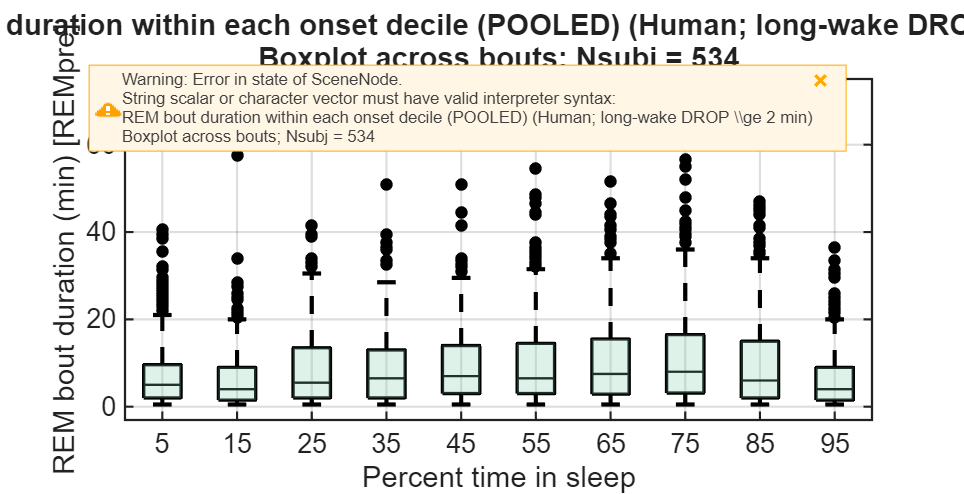



if SAVE_FIG
    outDir = fileparts(outPng_dur);
    if ~isfolder(outDir), mkdir(outDir); end
    exportgraphics(gcf, outPng_dur, 'Resolution', 300);
    fprintf('Saved: %s\n', outPng_dur);
end

%% ---------------- Boxplot: Panel (3) REM bout duration by onset decile ----------------
figure('Color','w','Position',[150 150 860 440]);

lbl3 = strings(nDec,1);
for bi = 1:nDec
    lbl3(bi) = sprintf('%.0f', binMids(bi));
end

boxplot(y, b, ...
    'Labels', cellstr(lbl3), ...
    'Symbol', 'k.', ...
    'Whisker', 1.5, ...
    'Colors', [0 0 0]);

hOut = findobj(gca,'Tag','Outliers');
set(hOut, 'Marker','o', 'MarkerSize',7, ...
    'MarkerEdgeColor','k', 'MarkerFaceColor','k');

grid on; box on;
xlabel('Percent time in sleep');
ylabel(sprintf('REM bout duration (min) [%s]', REMDUR_NAME));

title({sprintf('REM bout duration within each onset decile (POOLED) (Human; long-wake DROP \\ge %d min)', WAKE_BREAK_MIN), ...
       sprintf('Boxplot across bouts; Nsubj = %d', nSubj_included)}, ...
       'Interpreter','tex');

set(gca,'FontSize',16);
set(gca,'LineWidth',1.3);

set(findobj(gca,'Tag','Box')    , 'LineWidth',2.0, 'Color',[0 0 0]);
set(findobj(gca,'Tag','Median') , 'LineWidth',2.4, 'Color',[0 0 0]);
set(findobj(gca,'Tag','Whisker'), 'LineWidth',2.5, 'Color',[0 0 0]);
set(findobj(gca,'Tag','Cap')    , 'LineWidth',2.5, 'Color',[0 0 0]);

ax = gca;
hW = findobj(ax,'Tag','Whisker');
if isempty(hW)
    hW = [findobj(ax,'Tag','Upper Whisker'); findobj(ax,'Tag','Lower Whisker')];
end
set(hW,'LineWidth',2.5);

hC = findobj(ax,'Tag','Cap');
if isempty(hC)
    hC = [findobj(ax,'Tag','Upper Adjacent Value'); findobj(ax,'Tag','Lower Adjacent Value')];
end
set(hC,'LineWidth',2.5);

hold on;
COL = [0.20 0.70 0.50];
cFill = lighten_color(COL, 0.35);

h = findobj(gca,'Tag','Box');
h = flipud(h);
for j = 1:numel(h)
    xd = get(h(j),'XData');
    yd = get(h(j),'YData');
    patch(xd, yd, cFill, 'FaceAlpha',0.25, 'EdgeColor','none');
end

med = findobj(gca,'Tag','Median');
set(med,'Color',[0 0 0],'LineWidth',1.4);
hold off;


if SAVE_FIG
    outPng_dur_box = fullfile(combinedFolder,'tables_out', ...
        sprintf('Fig_REM_deciles_meanBoutDur_ONSET_POOLED_BOXPLOT_longwake%g_IQRsubj.png', WAKE_BREAK_MIN));
    exportgraphics(gcf, outPng_dur_box, 'Resolution', 300);
    fprintf('Saved: %s\n', outPng_dur_box);
end

%% ---------------- Save subject count filter table ----------------
if SAVE_TAB && APPLY_SUBJECT_CYCLECOUNT_IQR_FILTER && ~isempty(cycleCountTab)
    outDir = fullfile(combinedFolder,'tables_out');
    if ~isfolder(outDir), mkdir(outDir); end

    q1 = local_quantile(cycleCountTab.KeptCycleCount, 0.25);
    q3 = local_quantile(cycleCountTab.KeptCycleCount, 0.75);
    iqrVal = q3 - q1;
    lo = q1 - IQR_K * iqrVal;
    hi = q3 + IQR_K * iqrVal;

    cycleCountTab.LowerBound = repmat(lo, height(cycleCountTab), 1);
    cycleCountTab.UpperBound = repmat(hi, height(cycleCountTab), 1);
    cycleCountTab.IsOutlier  = cycleCountTab.KeptCycleCount < lo | ...
                               cycleCountTab.KeptCycleCount > hi;

    outCsv = fullfile(outDir, ...
        sprintf('subject_cyclecount_IQRfilter_REMdistribution_longwake%g.csv', WAKE_BREAK_MIN));
    writetable(cycleCountTab, outCsv);
    fprintf('Saved subject cycle-count filter table: %s\n', outCsv);
end

Saved subject cycle-count filter table: C:\Users\naghm\OneDrive\Desktop\combined_out\tables_out\subject_cyclecount_IQRfilter_REMdistribution_longwake2.csv



fprintf('Done.\n');

Done.



%% ---------------- Functions ----------------
function L = overlap_len(a1, a2, b1, b2)
% Length of overlap between [a1,a2] and [b1,b2]
    if ~(isfinite(a1) && isfinite(a2) && isfinite(b1) && isfinite(b2))
        L = 0;
        return;
    end
    if a2 <= a1 || b2 <= b1
        L = 0;
        return;
    end
    L = max(0, min(a2,b2) - max(a1,b1));
end

function q = local_quantile(x, p)
% Toolbox-free quantile with linear interpolation
    x = x(isfinite(x));
    if isempty(x)
        q = NaN;
        return;
    end

    x = sort(x(:));
    n = numel(x);

    if n == 1
        q = x;
        return;
    end

    pos = 1 + (n-1)*p;
    lo  = floor(pos);
    hi  = ceil(pos);

    if lo == hi
        q = x(lo);
    else
        q = x(lo) + (pos-lo) * (x(hi)-x(lo));
    end
end

function c2 = lighten_color(c, amount)
    c = double(c(:))';
    amount = max(0, min(1, amount));
    c2 = c + (1 - c)*amount;
    c2 = max(0, min(1, c2));
end

function [p, obs] = paired_signflip_pvalue(x, y, B)
% Toolbox-free paired sign-flip test for mean difference
% H0: mean(x-y)=0
    d = x - y;
    d = d(isfinite(d));

    if nargin < 3
        B = 20000;
    end

    if isempty(d)
        p = NaN;
        obs = NaN;
        return;
    end

    obs = mean(d);

    n = numel(d);
    nullStats = zeros(B,1);
    for b = 1:B
        sgn = 2*(rand(n,1) > 0.5) - 1;   % +/-1
        nullStats(b) = mean(sgn .* d);
    end

    p = mean(abs(nullStats) >= abs(obs));
end

function [p, Tobs] = decile_permutation_pvalue_within_subject(REMdur_min_all, valid_dur, G3, nDec)

    B = 20000;

    REM_onsetFrac = evalin('caller', 'REM_onsetFrac');
    valid_dur_loc = valid_dur(:);
    G3loc = G3(:);

    binEdges = linspace(0,1,11);
    binID_all = discretize(REM_onsetFrac, binEdges);
    atRightEdge = (REM_onsetFrac == binEdges(end));
    binID_all(atRightEdge) = nDec;

    ok = isfinite(binID_all) & ~isnan(binID_all) & ...
         (binID_all >= 1) & (binID_all <= nDec) & valid_dur_loc;

    y = REMdur_min_all(ok);
    b = double(binID_all(ok));
    g = double(G3loc(ok));

    [~,~,gRel] = unique(g);
    nSubj = max(gRel);

    Mobs = NaN(nSubj, nDec);
    for s = 1:nSubj
        idx = (gRel == s);
        bs = b(idx);
        ys = y(idx);
        for d = 1:nDec
            yd = ys(bs == d);
            if ~isempty(yd)
                Mobs(s,d) = mean(yd, 'omitnan');
            end
        end
    end

    Tobs = decile_effect_stat(Mobs);

    Tnull = zeros(B,1);
    for bb = 1:B
        bperm = b;
        for s = 1:nSubj
            idx = find(gRel == s);
            if numel(idx) >= 2
                bperm(idx) = bperm(idx(randperm(numel(idx))));
            end
        end

        Mp = NaN(nSubj, nDec);
        for s = 1:nSubj
            idx = (gRel == s);
            bs = bperm(idx);
            ys = y(idx);
            for d = 1:nDec
                yd = ys(bs == d);
                if ~isempty(yd)
                    Mp(s,d) = mean(yd, 'omitnan');
                end
            end
        end
        Tnull(bb) = decile_effect_stat(Mp);
    end

    p = mean(Tnull >= Tobs);
end

function T = decile_effect_stat(M)
% Global between-decile effect statistic based on subject-level centered means.
    subjMean = mean(M, 2, 'omitnan');
    Mcent = M - subjMean;
    colEff = mean(Mcent, 1, 'omitnan');
    colEff(~isfinite(colEff)) = 0;
    T = sum(colEff.^2);
end
